**Teoria de Controle Discreto**

**Projeto do Controlador RST por alocação de polos**

Ts = 10;
k=0;

Gden = [0.09554 0.09554];
%Gden = Gden(Gden~=0)';
Gnum = [1 0.7147 0.2566];
%Gnum = Gnum(Gnum~=0)';

nHs = 1;  % convolução com (1-z^-1)
Gden = conv(Gden,[1 -1]);

nHr = 0; %atraso nHr de todos os regressores

na = length(Gden)-1

na = 2

nb = length(Gnum)+nHr

nb = 3

ns = nb+nHr+k-1

ns = 2

nr = na+nHs-1

nr = 2

np = nb+na+nHs+nHr+k-1

np = 5


M = zeros(na+nb+k);

for i=1:nb+k
    M(:,i) = [zeros(i-1,1); Gden'; zeros(nb+k-i,1)]; 
end
for i=1:na
    M(:,i+nb+k) = [zeros(i+nHr,1); Gnum'; zeros(na+k-i,1)]; 
end

M

M =     0.0955         0         0         0         0
         0    0.0955         0    1.0000         0
   -0.0955         0    0.0955    0.7147    1.0000
         0   -0.0955         0    0.2566    0.7147
         0         0   -0.0955         0    0.2566


**Modelo em Malha Fechada**

    Sistema de primeira ordem com resposta mais rápida

Tass = 400;
qsi = 1;
wn = 4/(qsi*Tass);
Gmfcont = tf([wn^2],[1 2*qsi*wn wn^2]);
Gmfdisc = c2d(Gmfcont,Ts,'zoh')

Gmfdisc =
 
  0.004679 z + 0.004377
  ---------------------
  z^2 - 1.81 z + 0.8187
 
Sample time: 10 seconds
Discrete-time transfer function.
Model Properties


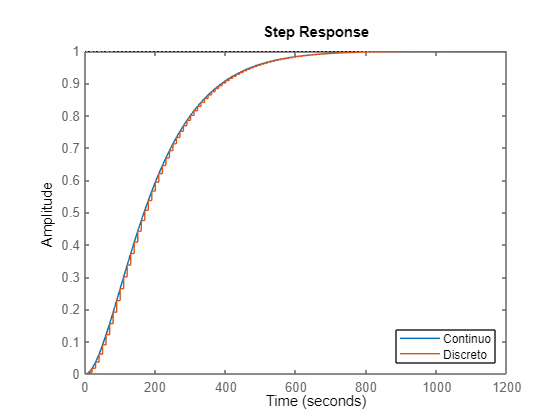


figure(8)
hold on
step(Gmfcont)
step(Gmfdisc)
legend("Continuo","Discreto",'Location','southeast')

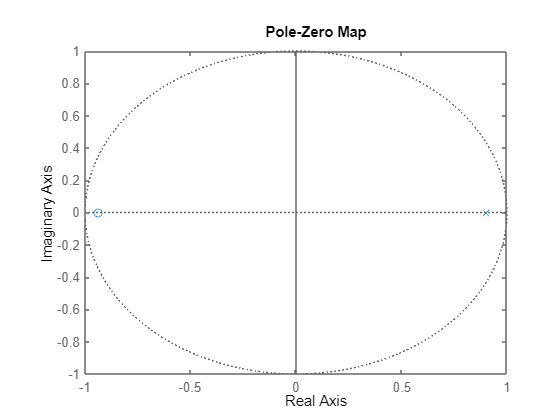

figure(9)
pzmap(Gmfdisc)

cell2mat(Gmfdisc.den)

ans =     1.0000   -1.8097    0.8187


qtdpdom = length(cell2mat(Gmfdisc.den))-1

qtdpdom = 2

qtdpaux = np-qtdpdom

qtdpaux = 3


regpaux = 0;

p = cell2mat(Gmfdisc.den)

p =     1.0000   -1.8097    0.8187



for i=1:qtdpaux-1
    p = conv(p,[1 -regpaux*rand()]);
end
p = p' 

p =     1.0000
   -1.8097
    0.8187
         0
         0


Gaux = tf(1,p',Ts);
figure(10)
pzmap(Gaux)
title("Polos em Malha fechada")
RS = M\p

RS =    10.4668
   16.0758
    8.9978
   -3.3456
    3.3502


S = conv(RS(1:ns+1),[1 -1])'

S =    10.4668    5.6090   -7.0780   -8.9978


R = RS(ns+2:end)'

R =    -3.3456    3.3502


T = sum(R)

T = 0.0046

theta = [-0.5147 -0.3566 0.15554 0.1240 0.9845];
%Gnum = Gnum(Gnum~=0)';

Ts = 10;
k=0;

Gden = [1 -theta(1) -theta(2) -theta(3)];
Gnum = [theta(4) theta(5)];

nHs = 1;  % convolução com (1-z^-1)
Gden = conv(Gden,[1 -1]);

nHr = 0; %atraso nHr de todos os regressores

na = length(Gden)-1;
nb = length(Gnum)+nHr;
ns = nb+nHr+k-1

ns = 1

nr = na+nHs-1

nr = 4

np = nb+na+nHs+nHr+k-1

np = 6


M = zeros(na+nb+k);

for i=1:nb+k
    M(:,i) = [zeros(i-1,1); Gden'; zeros(nb+k-i,1)]; 
end
for i=1:na
    M(:,i+nb+k) = [zeros(i+nHr,1); Gnum'; zeros(na+k-i,1)]; 
end
M

M =     1.0000         0         0         0         0         0
   -0.4853    1.0000    0.1240         0         0         0
   -0.1581   -0.4853    0.9845    0.1240         0         0
   -0.5121   -0.1581         0    0.9845    0.1240         0
    0.1555   -0.5121         0         0    0.9845    0.1240
         0    0.1555         0         0         0    0.9845


%Modelo em Malha Fechada
%    Sistema de segunda ordem com resposta mais rápida
%Tass = 400;
%qsi = 1;
%wn = 4/(qsi*Tass);
%Gmfcont = tf([wn^2],[1 2*qsi*wn wn^2]);
%Gmfdisc = c2d(Gmfcont,Ts,'zoh');

%qtdpdom = length(cell2mat(Gmfdisc.den))-1;

polos = [1 -1.8097 0.8187];
qtdpdom = length(polos)-1;
qtdpaux = np-qtdpdom

qtdpaux = 4


regpaux = 0;

polos = [polos zeros(1,qtdpaux-1)];

polos = polos' 

polos =     1.0000
   -1.8097
    0.8187
         0
         0
         0


RS = M\polos

RS =     1.0000
   -1.3580
    0.2706
    0.4144
   -0.8914
    0.2145


S = conv(RS(1:ns+1),[1 -1])

S =     1.0000   -2.3580    1.3580


R = RS(ns+2:end)'

R =     0.2706    0.4144   -0.8914    0.2145


T = sum(R)

T = 0.0081

%Modelo em Malha Fechada
%    Sistema de segunda ordem com resposta mais rápida
Ts=10;
Tass = 400;
qsi = 1;
wn = 4/(qsi*Tass);
Gmfcont = tf([wn^2],[1 2*qsi*wn wn^2]);
Gmfdisc = c2d(Gmfcont,Ts,'zoh')

Gmfdisc =
 
  0.004679 z + 0.004377
  ---------------------
  z^2 - 1.81 z + 0.8187
 
Sample time: 10 seconds
Discrete-time transfer function.
Model Properties


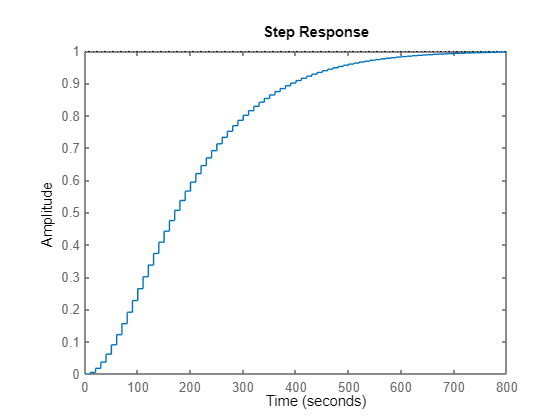

step(Gmfdisc)

Gmfdisc.num

ans = 1×1 cell array
    {[0 0.0047 0.0044]}


Gmfdisc.den

ans = 1×1 cell array
    {[1 -1.8097 0.8187]}
